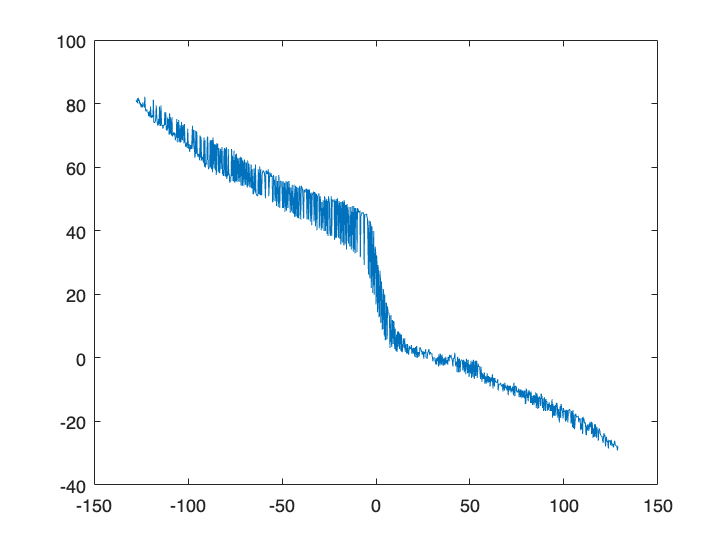

damperConst = readmatrix('FRUCDDamperdata.xlsx');
damperConst = damperConst(2:end,[2,4]);
damperForce = (damperConst(:,1)) * 4.44822;
damperVelocity = damperConst(:,2) * 25.4;

damperVelocity = round(damperVelocity, 3);
[damperVelocity, sortIndex] = sortrows(damperVelocity);
[damperVelocity,uniqueIndex] = unique(damperVelocity);
damperForce = damperForce(sortIndex);
damperForce = damperForce(uniqueIndex);
plot(damperVelocity, damperForce);


polyDamp20 = polyfit(damperVelocity,damperForce,20);


polyDamp20

polyDamp20 =     0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0019   -0.0111   -1.7417   25.9154


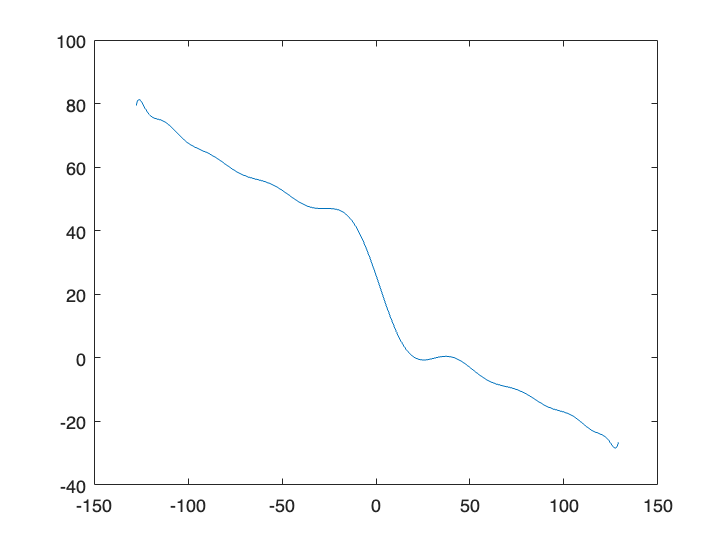

damperForcePoly = polyval(polyDamp20, damperVelocity);
plot(damperVelocity,damperForcePoly);

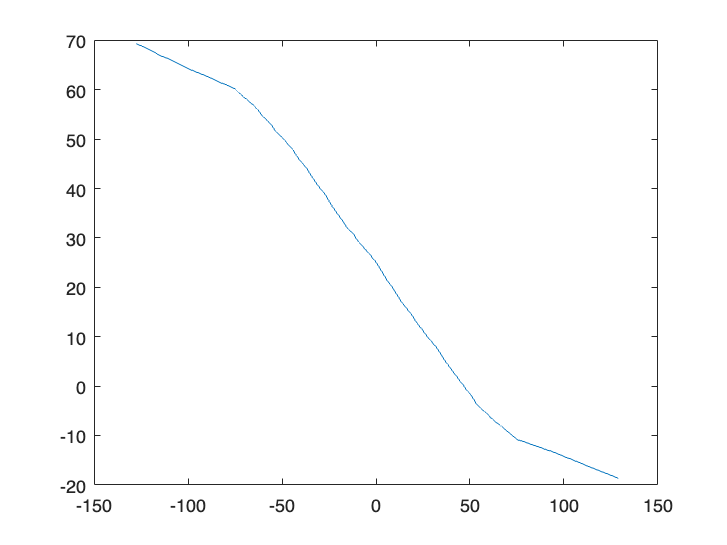



x = linspace(min(damperVelocity), max(damperVelocity), 10000);
damperForce = smoothdata(damperForce,1);
inDamp = interp1(damperVelocity,damperForce,x, 'linear');

plot(x,inDamp)

inDamp = interp1(damperVelocity,damperForce, x, 'makima');
